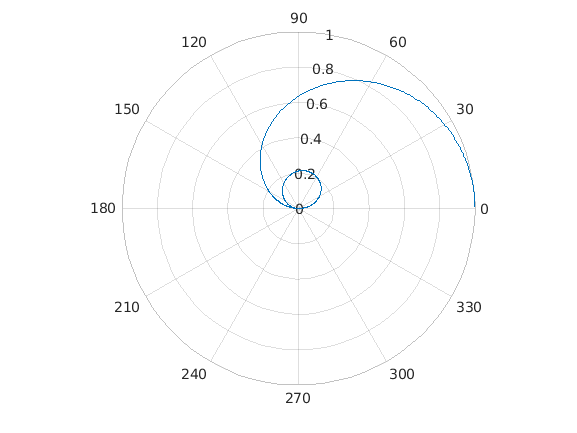

x1 = 0:0.01:2*pi;
y1 = sin(x1)./x1;
polarplot(x1,y1)

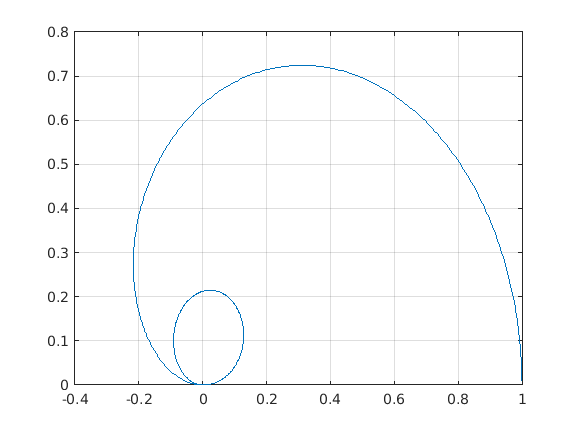

x2 = y1.*cos(x1);
y2 = y1.*sin(x1);
plot(x2,y2);
grid on;

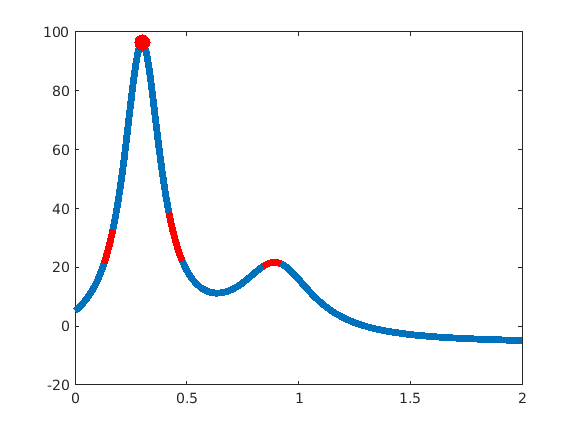


o = 0:0.01:2;
op = humps(o(1:length(o)));
plot(o,op, "LineWidth", 5);
hold on;
j = 1;
op2 = zeros(1, 200);
o2 = zeros(1, 200);
for i = 1:length(o)
    if op(i) >= 20 && op(i) <= 40
        op2(j) = op(i);
        o2(j) = o(i);
        j = j+1;
    end
end
op3 = op2(1:j-1);
o3 = o2(1:j-1);

j = 1;
for i = 1:length(o3)-1;
    if o3(i) + 0.01 < o3(i+1)
        op4 = op3(j:i-1);
        o4 = o3(j:i-1);
        plot(o4, op4,"color", "red", "LineWidth", 5);
        j = i+1;
        hold on;
    end
end
op4 = op3(j:i-1);
o4 = o3(j:i-1);
plot(o4, op4,"color", "red", "LineWidth", 5);
hold on;
j = 0;
jp = -100;
for i = 1:length(o)
    if op(i) > jp
        j = i;
        jp = op(i);
    end
end
plot(o(j), op(j),'.', 'MarkerSize', 40, "color", "red");